# `Google's PageRank`

## `History:`

`        Sergey Brin and Larry Page founded the Web search engine company Google, Inc. in September 1998.Although many factors determine Google’s overall ranking of search engine results, Google maintains that the heart of its search engine software is PageRank. Both developed a ranking algorithm, named PageRank after Larry Page, that uses the link structure of the Web to determine the importance of webpages.`

### `What is Page Rank algorithm?`

` PageRank is an algorithm used by Google Search to rank web pages in their search engine results. PageRank is a way of measuring the importance of website pages.Currently, PageRank is not the only algorithm used by Google to order search results, but it is the first algorithm that was used by the company, and it is the best known.`

`Maximizing the PageRank score of a webpage, has become an important component of company marketing strategies. The academic community recognizes that PageRank has connections to numerous areas of mathematics and computer science such as matrix theory, numerical analysis, information retrieval, and graph theory. As a result, much research continues to be devoted to explaining and improving PageRank. The PageRank score of a webpage represents the probability that a random Web surfer chooses to view the webpage.`

`Let's see the Mathamatics behind this.,`

#### `Directed web graph:`

- `Each and every ``node`` here represent a ``webpage``.`

- `links from webpages to other webpages are ``edges`` that ``show direction of movement``.`

- `Following Graph Shows a directed graph`

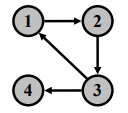

`Figure:1`

#### `Web Hyperlink Matrix:`

`Hense the intial stage for determing Page rank is by expressing the given web graph as `$n\times n$ `Hyper link matrix``.`


$$H=\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
0 & 0 & 1 & 0\\
\frac{1}{2} & 0 & 0 & \frac{1}{2}\\
0 & 0 & 0 & 0
\end{array}\right\rbrack$$


$H$` = Hyperlink Matrix `

$H_{i,j}$`= Likelihood that a random surfer selects a link from webpage `$i$ $\longrightarrow$` webpage `$j$

$H_{i,j}$` = `$\frac{1}{l_i }$ `, `$l_i$ $\longrightarrow$`Link from webpage `$i$`.`

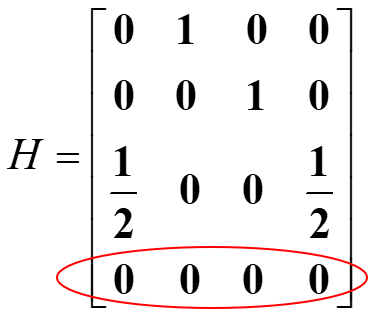

`Here we can see that the node 4 is a dangling node i.e., it dose not linked with any other node in the graph. So by this we can say that the probability that a Random Surfer move to the any other node is considerd as 0.`

`Let's See how to Fix Dangling Node:`

- `As there are many way to solve this issue when a webserver lands in dangling node.`

- `Let us See that replacing the dangling row of H by the same probability distribution vector, w.`

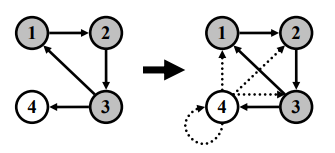

`Figure:2`

`Now, Google Creates a new matrix `$S=H+\textrm{dw}$

`d` $\longrightarrow$` Colum vecor which identifies the dangling node.`

`w` $\longrightarrow$` Sample Probability vector. `$\Rightarrow$ $w$$\longrightarrow$ $\left\lbrack \begin{array}{ccccc}
\frac{1}{n} & \frac{1}{n} & \frac{1}{n} & \cdots  & \frac{1}{n}
\end{array}\right\rbrack$

`n` $\longrightarrow$` number of nodes (or) web pages`


$$S=\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
0 & 0 & 1 & 0\\
\frac{1}{2} & 0 & 0 & \frac{1}{2}\\
0 & 0 & 0 & 0
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0\\
0\\
1
\end{array}\right\rbrack \left\lbrack \begin{array}{cccc}
\frac{1}{4} & \frac{1}{4} & \frac{1}{4} & \frac{1}{4}
\end{array}\right\rbrack$$

$$\Rightarrow$$
 
$$S=\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
0 & 0 & 1 & 0\\
\frac{1}{2} & 0 & 0 & \frac{1}{2}\\
\frac{1}{4} & \frac{1}{4} & \frac{1}{4} & \frac{1}{4}
\end{array}\right\rbrack \;$$


`For the graph in Figure:2, there is no directed edge from node 2 to node 1. On the Web, though, a surfer can move directly from node 2 to node 1 by entering the URL for node 1 in the address line of a Web browser. ``The matrix S does not consider this possibility.`

- `So Solution for this problem is, Google matix!.`

`Google Matrix:`

$G=\alpha S+\left(1-\alpha \right)$`1`$\nu$

$\alpha$$\longrightarrow$` damping factor, `$0\le \alpha <1$`;`` [Suggested to take value from 0.85 to 0.99`

`1 `$\longrightarrow$` Column Vector of ones.`

$\nu$ $\longrightarrow$` Row Probability distribution Matrix (or) Personalization matrix`


$$\nu$$

$$\longrightarrow$$
 
$$\left\lbrack \begin{array}{ccccc}
\frac{1}{n} & \frac{1}{n} & \frac{1}{n} & \cdots  & \frac{1}{n}
\end{array}\right\rbrack$$


        `Caution!, `

- `Here The uniform vector `$\nu$` has High susceptible to link spamming, So Google dosen't use it to  determine actual page rank score.`

- `Link spamming is the practice by some search engine optimization experts of adding more links to their clients’ webpages for the sole purpose of increasing the PageRank score of those webpages.`

- `This attempt to manipulate PageRank scores is one reason Google does not reveal the current damping factor or personalization vector for the Google matrix.`

- `In 2004, however, Gyongyi, Garcia-Molina, and Pederson developed the TrustRank algorithm to create a personalization vector that decreases the harmful effect of link spamming, and Google registered the trademark for TrustRank on March 16, 2005.`

`Note:`

`We can find page rank ` `iteratively or algebraically,`` Following I have shown algebrical approch.`

`Power Method:`

`    Is the one of the oldest and prowerful method for approximating a dominant eigenvector of a matrix.`

`     Consider a Eigent System `$\Pi G=\Pi$

`Let's See Algebric Way of finding the Page rank,`

`Although Brin and Page originally defined PageRank as a solution to the eigensystem `$\Pi G=\Pi$` the problem can be restated as a linear system. `

`Since `$G=\alpha S+\left(1-\alpha \right)$`1`$\nu$` and Transforming `$\Pi G=\Pi$` to `$0=\Pi -\Pi G$

                                                            
$$0=\Pi -\Pi G$$


                                                            
$$0=\Pi I-\Pi \left(\alpha S+\left(1-\alpha \right)\;1\nu \right)$$


                                                            
$$0=\Pi \left(I-\alpha S\;\right)-\left(\left(1-\alpha \right)\left(\Pi \;1\right)\nu \right)$$


                                                            
$$0=\Pi \left(I-\alpha S\;\right)-\left(\left(1-\alpha \right)\nu \right)$$
    
$$\left(\textrm{Since}\;\Pi \;1=1\right)$$


                                                            
$$\Pi \left(I-\alpha S\;\right)=\left(\left(1-\alpha \right)\nu \right)$$


- $\Pi$ $\longrightarrow$`row Probability distribution vector which is called ``Page Rank Vector.`

H = [0 1 0 0;0 0 1 0;0.5 0 0 0.5;0 0 0 0];
d = [0;0;0;1];
w = [0.25;0.25;0.25;0.25]';
S = H + d*w%Matrix for avoiding dangling.

S =                    0   1.000000000000000                   0                   0
                   0                   0   1.000000000000000                   0
   0.500000000000000                   0                   0   0.500000000000000
   0.250000000000000   0.250000000000000   0.250000000000000   0.250000000000000


%S = sym(S)
Alpha = 0.85;
One = ones(4,1);
Nue = [0.25; 0.25;0.25;0.25]';
G = Alpha*S +(1-Alpha)*One*Nue%Google Matrix

G =    0.037500000000000   0.887500000000000   0.037500000000000   0.037500000000000
   0.037500000000000   0.037500000000000   0.887500000000000   0.037500000000000
   0.462500000000000   0.037500000000000   0.037500000000000   0.462500000000000
   0.250000000000000   0.250000000000000   0.250000000000000   0.250000000000000


%GoogleMatrix_G = sym(G)
I = eye(4);
Phi1 = (1-Alpha)*Nue;
Phi2 = (I-Alpha*S);


$$\Pi \left(I-\alpha S\;\right)=\left(\left(1-\alpha \right)\nu \right)$$


`Hense Page rank Phi,`

Phi = (Phi1/Phi2);
sum(Phi)

ans =    1.000000000000000


PageRankVector = Phi

PageRankVector =    0.213762154076290   0.264622288706058   0.307853403141361   0.213762154076290


y=Phi;
temp=y;
ind=zeros(1,length(Phi));
for i=1:length(y)
    a=max(temp);
    inde=find(a==temp)
    temp(inde)=zeros(1,length(inde))
    ind(inde)=i*ones(1,length(inde))
    if temp==0
        break
    end
end

inde =      3


temp =    0.213762154076290   0.264622288706058                   0   0.213762154076290


ind =      0     0     1     0


inde =      2


temp =    0.213762154076290                   0                   0   0.213762154076290


ind =      0     2     1     0


inde =      1     4


temp =      0     0     0     0


ind =      3     2     1     3


Ordering_of_Nodes = ind

Ordering_of_Nodes =      3     2     1     3


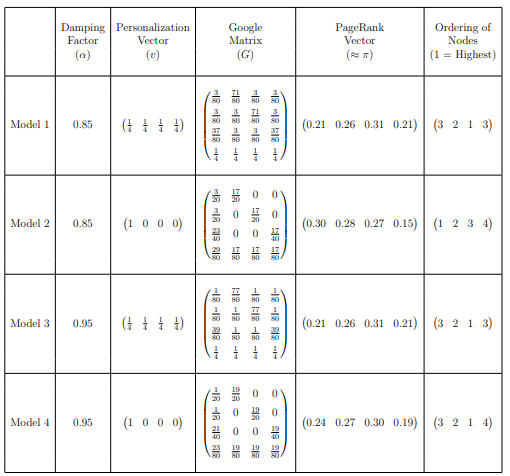

`The table indicates that the personalization vector has more influence on the PageRank scores for smaller damping factors. For instance, when `$\alpha =0\ldotp 85$`, ``as is the case for the first and second models, the PageRank scores and the ordering of the scores differ significantly.The first model assigns the uniform vector to `$\nu$`,`` and node 1 is one of the nodes with the lowest PageRank score. The second model uses `$\nu =\left(1\;\;0\;\;0\;\;0\right)$`, and node 1 receives the highest PageRank score.This personalization vector suggests that when Web surfers grow tired of following the link structure of the Web, they always move to node 1.For the third and fourth models,`$\alpha =0\ldotp 95$`.The difference in PageRank scores and ordering of scores for these models is less significant.Even though`$\nu =\left(1\;\;0\;\;0\;\;0\right)$`in the fourth model, the higher damping factor decreases the influence of `$\nu$`.`

`Power Iterative Algotihm:`

[V] = pagerank1(G,0.85,0.001)

V =    0.229469527723854
   0.229311705744780
   0.229616022718661
   0.229503319726489


`Following is the Iterative method for finding the rank of a given Hyperlink matrix`

- `Parameter M adjacency matrix where M_i,j represents the link from 'j' to 'i', such that for all 'j' sum(i, M_i,j) = 1`

- `Parameter d damping factor`

- `Parameter v_quadratic_error quadratic error for v`

- `Return v, a vector of ranks such that v_i is the i-th rank from [0, 1]`

function [v] = pagerank1(M, d, v_quadratic_error)

N = size(M, 2); % N is equal to dimension of M 
v = rand(N, 1);
v = v ./ norm(v, 1);
last_v = ones(N, 1) * inf;
M_hat = (d .* M) + (((1 - d) / N) .* ones(N, N));

while (norm(v - last_v, 2) > v_quadratic_error)
	last_v = v;
	v = M_hat * v;
end

end